% set up for the script
clear; close all; clc;
% add the path to Cheng's prepared functions
addpath('/home/yasamanparhizkar/Documents/yorku/01_thesis/code/15_cheng/SGML-master/SGML_in_Matlab')

% load the data from disc
load('../../data/fe_exp/cheng_snap_3/data_30_50_2.mat')
train_des = cast(train_des, 'double');
train_lbls = train_lbls.';
train_num = size(train_des, 1);

% visualize the dataset
% figure;
% scatter(train_des(1:floor(train_num/2),1),train_des(1:floor(train_num/2),2),25,'red','filled');
% hold on;
% scatter(train_des(floor(train_num/2)+1:end,1),train_des(floor(train_num/2)+1:end,2),25,'blue','filled');
% legend('spike', 'no spike');
% hold off;

## Train the model

borrowed from RUN_ME.m from Cheng's code.

data_feature = train_des;
data_label = train_lbls;
clear train_des train_lbls % to save space
[n_sample,n_feature] = size(data_feature); % number of samples, number of features

%=main parameters for SGML=================================================
C=n_feature; % constraint of the trace of M
rho=1e-5; % tolerance to make sure M is positive definite during optimization
lobpcg_random_control=0; % random seed for computing the first eigenvector for the first time using LOBPCG
options = optimoptions('linprog','Display','none','Algorithm','interior-point'); % linear program (LP) setting for Frank-Wolfe algorithm
options.OptimalityTolerance = 1e-2; % LP optimality tolerance
options.ConstraintTolerance = 1e-4; % LP interior-point constraint tolerance
FW_dia_offdia_tol=1e-3; % Frank-Wolfe tolerance when optimizing the diagonals + one row/column of off-diagonals
FW_full_tol=1e-5; % Frank-Wolfe tolerance when optimizing the full metric matrix M
max_iter=1e3; % maximum number of iterations for each round of Frank-Wolfe optimization
%==========================================================================

%=parameters for Frank-Wolfe step size optimization========================
GS_or_NR=2; % Frank-Wolfe step size optimization using 1) golden section search or 2) Newton-Raphson method
tol_golden_search=5e-1; % tolerance of golden section search
tol_NR=5e-1; % Newton-Raphson tolerance
tol_GD=5e-1; % gradient descent bisection tolerance
%==========================================================================

%=other parameters=========================================================
gamma = 1; % relative importance of the different-labeled edges to same-labeled edges in the objective function
nv_od=2*n_feature-1; % number of LP variables when optimizing the diagonals + one row/column of off-diagonals
nv_full=n_feature+(n_feature*(n_feature-1))/2; % number of LP variables when optimizing the full metric matrix M
zz=logical(tril(ones(n_feature),-1)); % indices of the lower triangular part of M
dia_idx=(1:n_feature+1:n_feature^2)'; % indices of the diagonals of M
num_list=1:n_feature; % indices of graph nodes of M where the nodes are currently connected
league_vec = ones(n_feature,1); % color set of graph nodes of M
league_vec(2:2:end)=-1; % set it like this so that the odd nodes are blue and even nodes are red
bins=ones(1,n_feature); % the number of the unique numbers of bins represents the number of subgraphs of M
%==========================================================================

%=Initialize M=============================================================
% M0=initial_M(n_feature,2); % initial M as a [1-dense matrix] or [2-sparse matrix]
% 
% % [M0,league_vec] = determine_initial_M_appropriate_colors(data_cov,...
% %     n_feature,...
% %     [],...
% %     [],...
% %     [],...
% %     2);
% 
% rng(lobpcg_random_control);
% [fv1,~] = ...
%     lobpcg_fv(randn(n_feature,1),M0,1e-12,200); % compute the first eigenvector for the first time using LOBPCG

% load M0 and fv1
load('../../data/fe_exp/cheng_snap_3/M0andfv1_30_50_2.mat', 'M0', 'fv1');
scaled_M = (1./fv1) .* M0 .* fv1'; % compute the similarity-transformed M
scaled_factors = (1./fv1) .* ones(n_feature) .* fv1'; % get the scalars of M
%==========================================================================

[LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub] = LP_setting(n_feature,rho); % get parts of the linear constraints ready for running Matlab linprog

%=run SGML=================================================================
disp('**starting SGML.');

**starting SGML.


[M]=SGML_main_yasaman(M0,...
    data_feature,...
    data_label,...
    n_sample,...
    n_feature,...
    tol_NR,...
    tol_GD,...
    rho,...
    max_iter,...
    GS_or_NR,...
    tol_golden_search,...
    options,...
    FW_dia_offdia_tol,...
    FW_full_tol,...
    C,...
    gamma,...
    nv_od,...
    nv_full,...
    zz,...
    dia_idx,...
    num_list,...
    league_vec,...
    bins,...
    fv1,...
    scaled_M,...
    scaled_factors,...
    LP_A_sparse_i,...
    LP_A_sparse_j,...
    LP_A_sparse_s,...
    LP_b,...
    LP_lb,...
    LP_ub); % run SGML

initial objective value = -23597.7571
===trying with larger OptimalityTolerance===
===trying with larger OptimalityTolerance===
===trying with larger OptimalityTolerance===
===trying with larger OptimalityTolerance===
 
converged objective value = -11121124.3499
minimal eigenvalue of M = -26037.0703


disp('**done with SGML.');

**done with SGML.


%==========================================================================

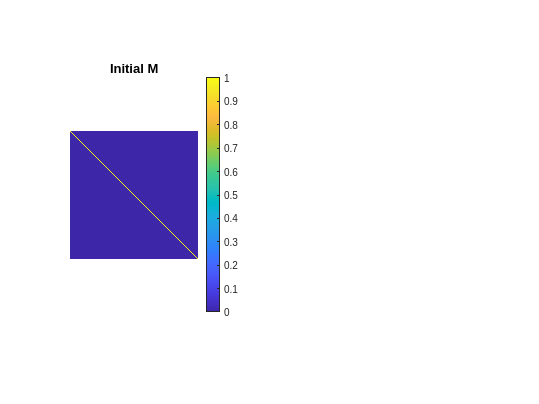

%% visualize the initial metric matrix M0
figure(1);subplot(1,2,1);imagesc(M0);title('Initial M');axis off equal;colorbar; % visual check M0

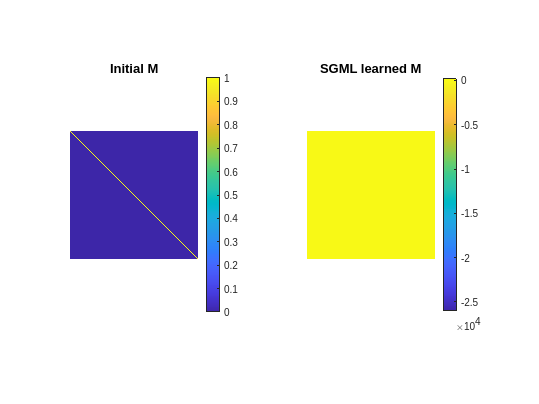

%% visualize the SGML learned metric matrix M
subplot(1,2,2);imagesc(M);title('SGML learned M');axis off equal;colorbar; % visual check M

## save the optimized metric matrix M

% fullM = full(M);
% save('../../data/fe_exp/cheng_snap/metric.mat', 'fullM')